# Introduction to MATLAB - Hands-On Workshop

Today, we will discuss how we can use MATLAB and its features to aid in data analysis. Using these features, we can manage our code better, spend more time on the actual data analysis, and improve the entire development process.

In this example, we will analyze data we gathered from a quadcopter simuation executed in Simulink. Quadcopters are notoriously difficult environments for collecting good sensor data. Quadcopters typically have on-board IMU sensors, comprised of 3 gyroscopes and 3 accelerometers. Any type of autonomous flight requires using this sensor data to estimate a full state (position, velocity, Euler angles, angular rates). This difficulty of this task increases greatly if the sensor data is noisy.

Unfortunately, the low-cost nature of most quadcopters drives the use of low-cost sensors, which tend to be significantly noisier than their vastly more expensive counterparts used in the aviation industry.

The issue of sensor noise is further exacerbated by the nature of the quadcopter airframe itself. The existence of 4 motors rotating 4 propellers at very high RPM (up to 30,000 RPM for the quadcopter hardware used in this example) create vibrations in the airframe that can pollute the sensor data.

The task for this flight test data is to analyze the IMU data and try to determine the sensor noise characteristics for use in a Kalman filter sensor fusion algorithm. It is important in this case to seperate sensor noise from airframe vibration in the data.

## Part 0: Presentation

***Note:*** Will not work within MATLAB Online

[Open Presentation](matlab:open('..\MATLAB_FlightDataAnalysis.pptx'))

## Part 1: Configuration Management, Source Control, and Live Scripts

### Part 1a: Configuration Management - Projects**

When working with a new code base, [MATLAB Projects](https://www.mathworks.com/help/matlab/projects.html) is a powerful tool to help organize our work and better collaborate with others. A project has already been created for this workshop.

**A)  Initialize the current Project**

Here, we will create a variable that will let us reference the current project. This will be helpful in accessing properties and paths of the project later on.

prj = currentProject;

**B)  Explore the Project**

To explore the Project, click on the project toolstrip.

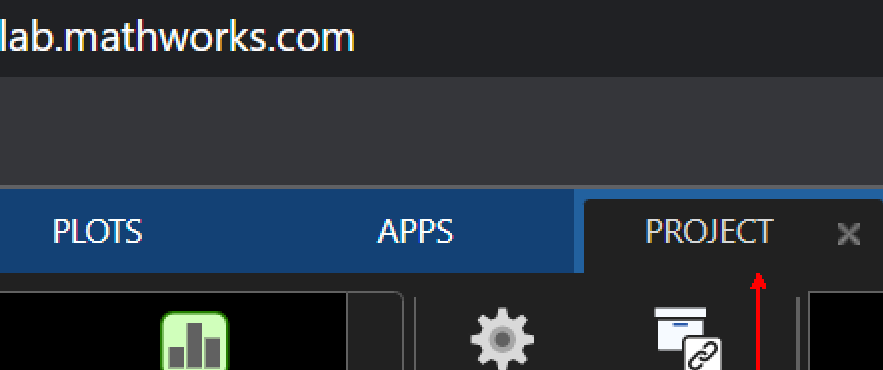

To view features and capabilities of the projects, explore the "Tools" gallery by opening the drop-down menu.

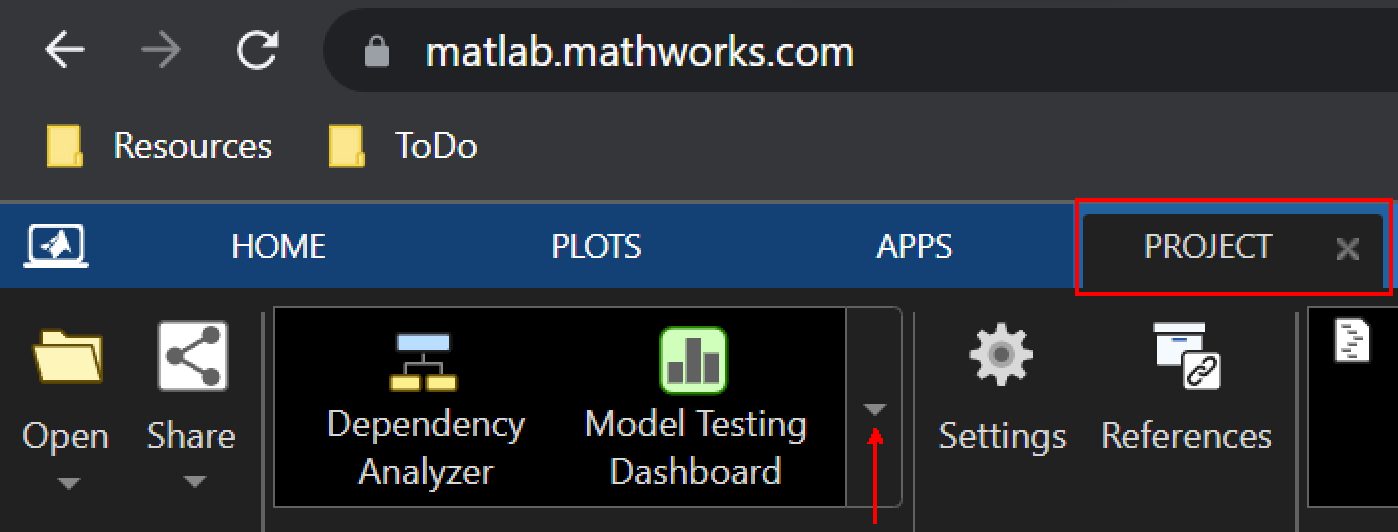

To change existing properties or attributes of the project, click the "Settings" icon. Here, we can edit things like project path, start-up and shut-down files, and shortcuts.

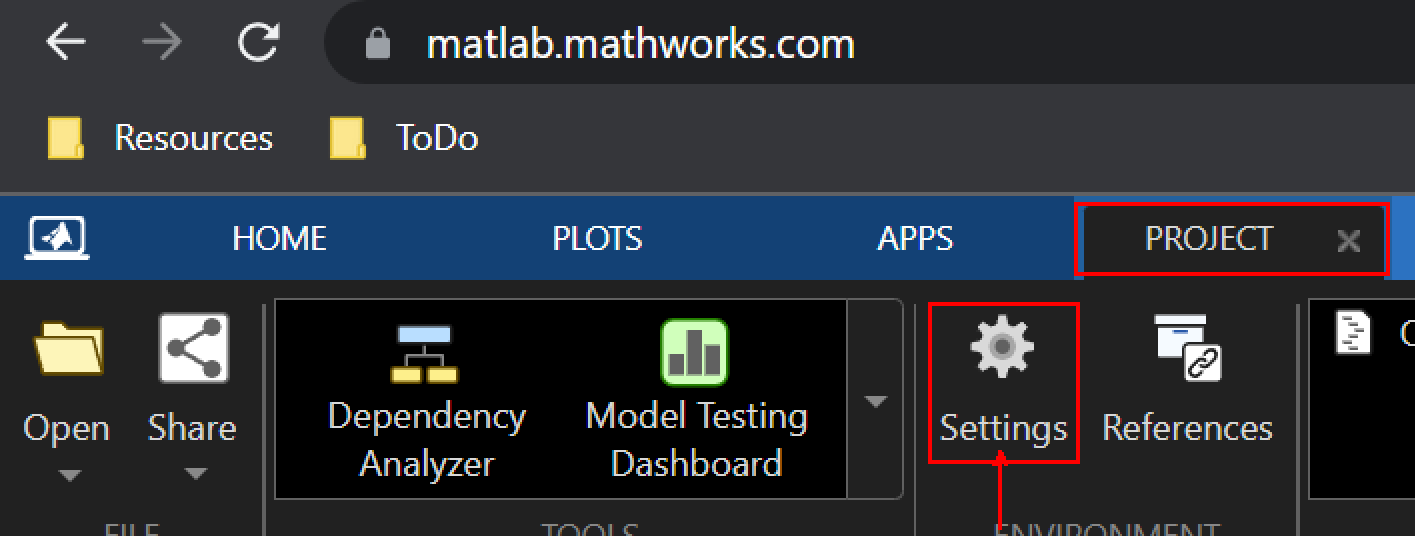

### Part 1b: Source Control

We will use MATLAB's built-in [source control integration](https://www.mathworks.com/help/matlab/source-control.html) to track the changes made to this repository.

When getting started with a new project, it might be useful to take a quick peek at the commit history of a repository to see:

- How much active work is going on in this repository?

- Are there multiple contributors to the repository?

- Do they use multiple branches to manage concurrent development?

- If I were to create a new branch for my work, is there a pattern to the names they use for their branches that I should follow?

- etc.

This can help feel like you are getting a head start in better understanding the team you are going to work with, and help fit in with their existing development workflow. The Branch Manager is a great way to explore the repository history!

**A)  Launch the Branch Manager**

To launch the Branch Manager, click on the **Branch Manager** icon in the project toolstrip.

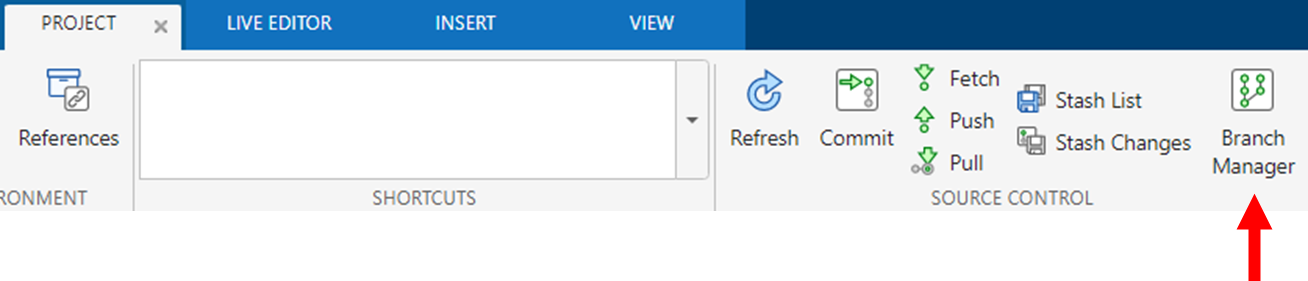

**B)  Explore the repository history**

The Branch Manager lets you:

- see the entire commit history and all files changed with each commit

- commit, merge, push, pull, and fetch changes

- create, switch, and delete branches and tags

- search commit messages

***Note:***  Double-clicking on the tab in the Branch Manager will expand the Branch Manager to fill your available window space. This can be helpful if the initial panel size is too small. 

**C)  Create a new branch for our workshop**

Let's create a new branch for the work we'll be doing during our workshop.

You can create a new branch using the **New Branch** icon in the toolstrip, and you can name the new branch whatever you'd like.

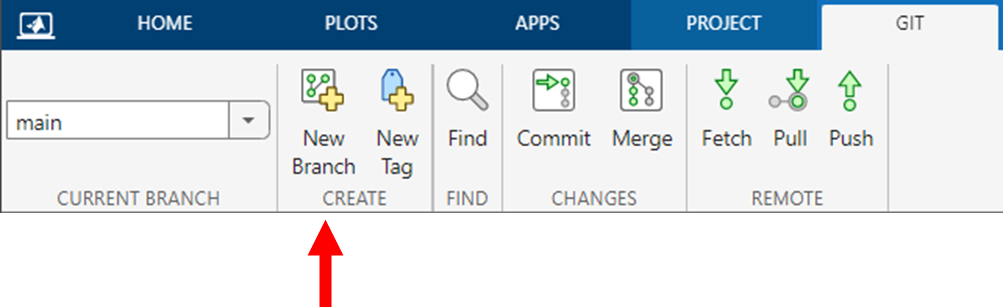

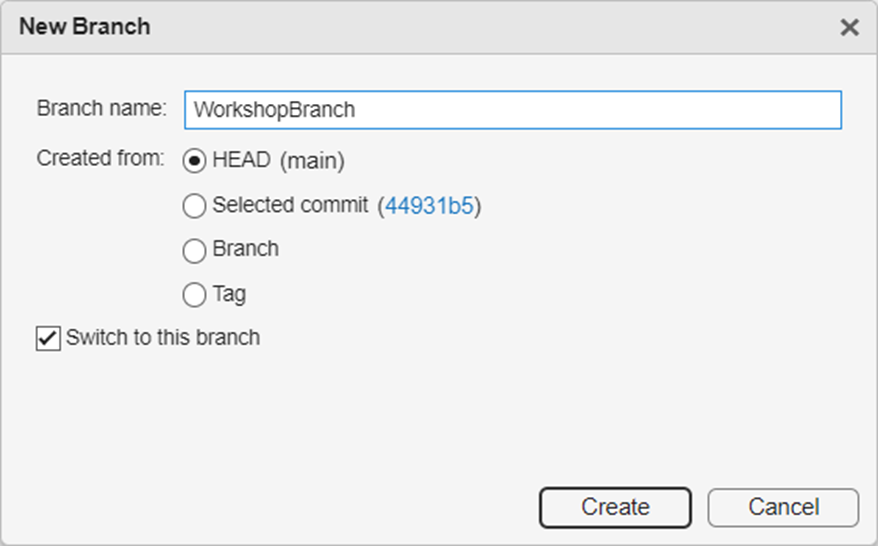

Once you've created your new branch, you can close the Branch Manager using the "X" on the Branch Manager tab. You're now ready to start making changes to the code in your own private branch!

### Part 1c: Live Scripts

Let us explore this document. This .mlx file is a [Live Script](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html). Live Scripts are interactive documents that combine MATLAB code with formatted text, equations, and images in a single environment called the Live Editor. Let's try recreating the image of the equation below:

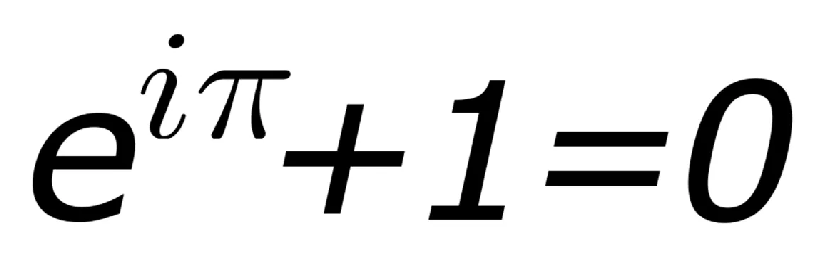

Written Equation: 


$$e^{i\pi } +1=0$$


We can also use Live Scripts to: 

- Easily build reports

- Utilize unique features like [live controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) and [live tasks](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html)

tempData = randi(1000,100,1);
if false
    disp("I have been checked")
end

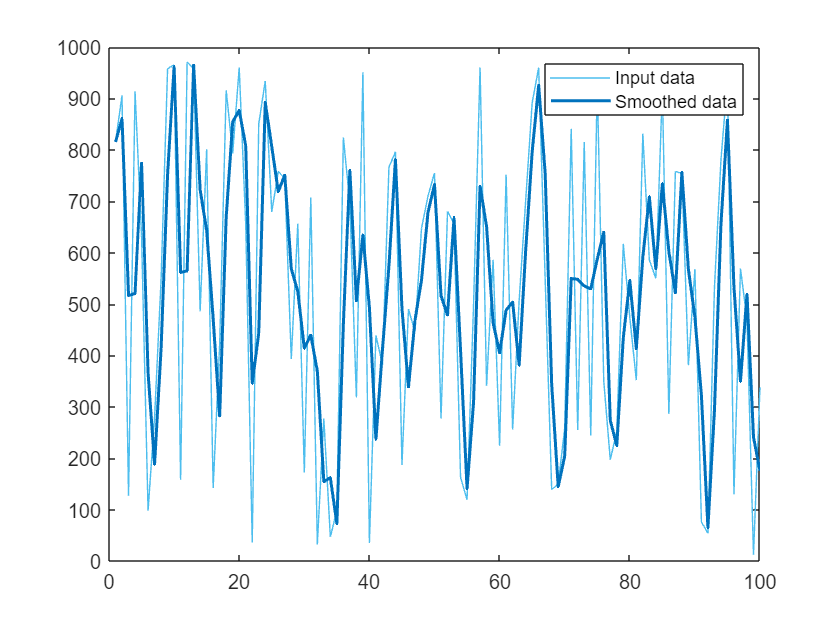

% Smooth input data
smoothedData = smoothdata(tempData,"movmean","SmoothingFactor",0.25);

% Display results
figure
plot(tempData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

- Interact with your data and plots more intuitively

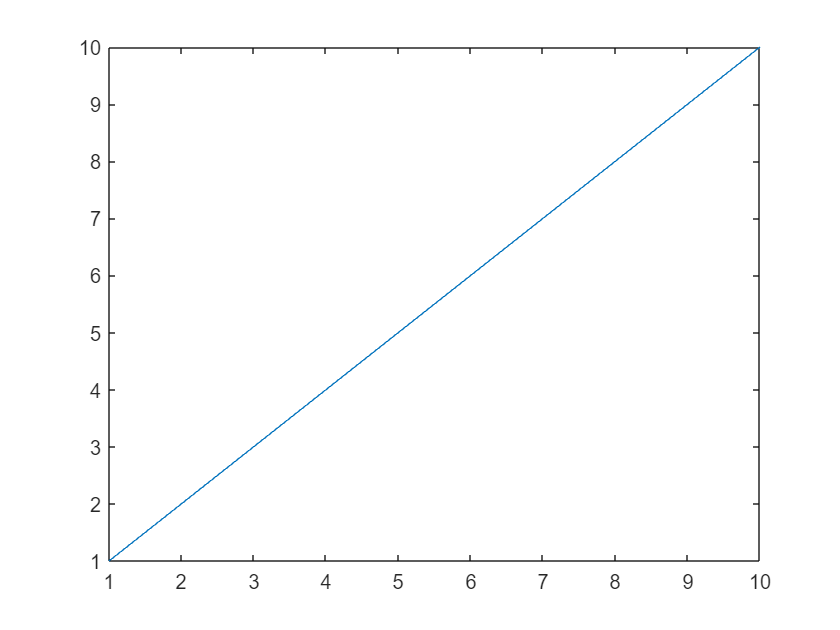

plot(1:10)

clear tempData

## Part 2: Analyze Flight Data - Access Input Data Using Import Tool

We can use the [Import Tool](https://www.mathworks.com/help/matlab/import_export/import-data-interactively.html) in MATLAB to import data from a file into MATLAB interactively. In the home toolstrip, select the **Import Data** icon.

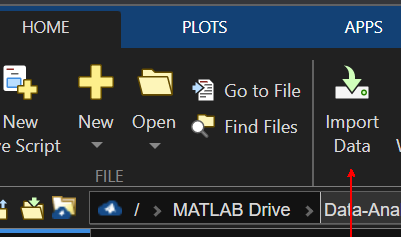

Open the data file (*"Data/testFlightTestData.csv"*). Let's explore some features of the Import Tool. 

One feature is the ability to directly import data into our workspace.

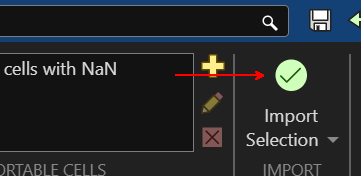

We saw how we can import our data directly into the workspace. This may not be convenient if we have many files. Note that after setting up the App to import the data, you can instead select the option to **Generate Function**. This will automatically create a MATLAB function that will replicate the data import as performed through the App.

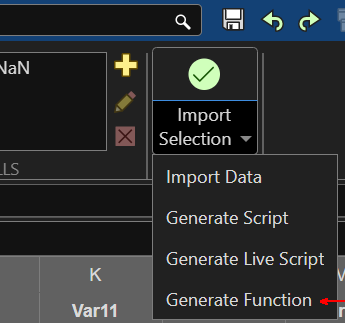

Let's create a new variable, **"myData"**, and use our newly-generated function from earlier to pull in our final dataset (*"Data/flightTestData.csv"*).

myData = importFlightTestData("flightTestData.csv");

We will convert time from string format to "[datetime](https://www.mathworks.com/help/matlab/ref/datetime.html)" format since we are working with time-series data.

myData.time = datetime(myData.time,'Format', 'u::DDD:HH:mm:ss.SS');

## Part 3: Analyze Flight Data - Visualize

Let's visualize our data by exploring our options in the plots gallery in the plots toolstrip. First, let's open up our data by double clicking on our **"myData" **variable. Here, we will open the "Variables" window where we can select some data we want to visualize. Once selected, let's plot it and customize it within the live script and using the **Properties Browser** in the figure window. Again, we want to automate this process so let's use the option to **Generate Function**.

Let's take a look at some examples extending this capability.

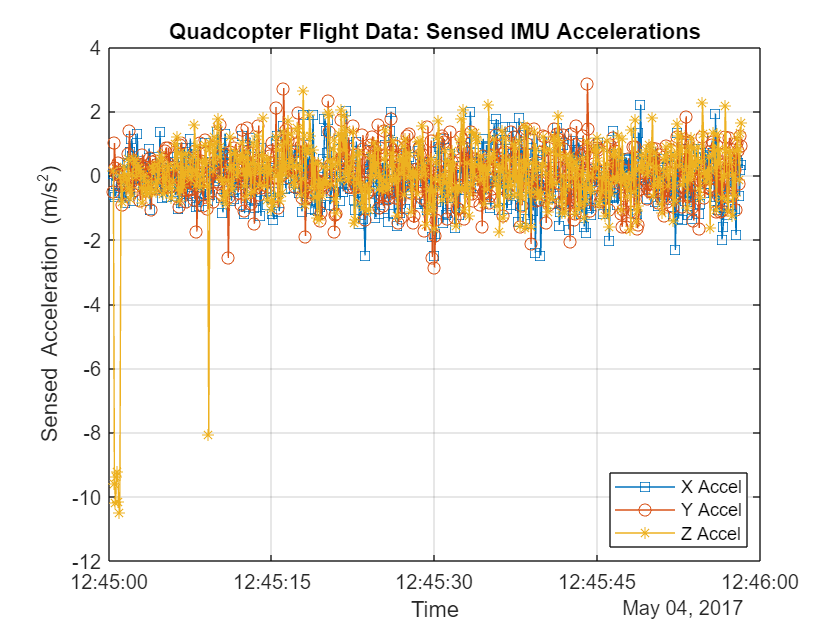

%IMU Data: Translational Acceleration
plotIMUaccels(myData.time, [myData.accX_body myData.accY_body myData.accZ_body])

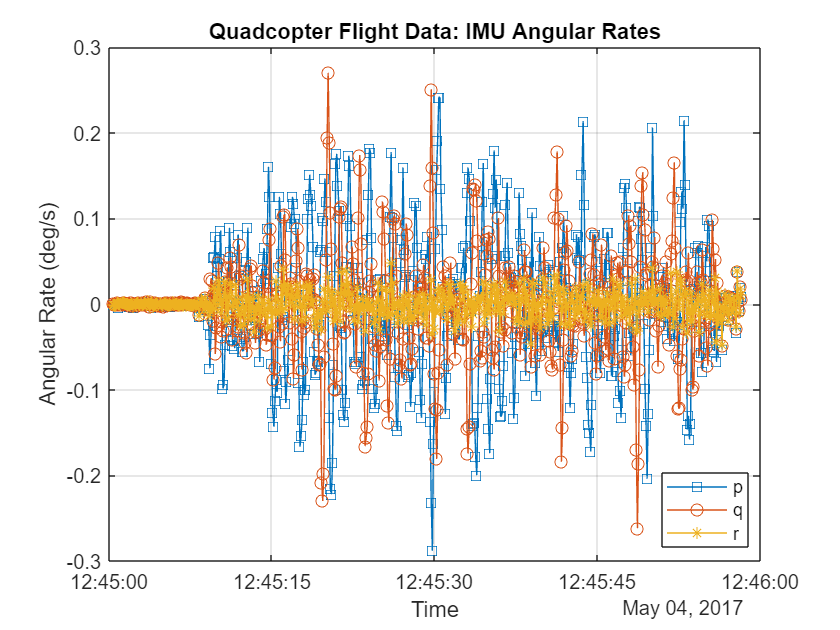

%IMU Data: Angular Rates
plotAngRates(myData.time, [myData.p myData.q myData.r])

**A)  Tiled Layout**

The plots above are a little messy so let's use individual plots for each axis. Here, we will use the new '[tiledlayout](https://www.mathworks.com/help/matlab/ref/tiledlayout.html)' option to re-plot our IMU data in the X, Y, and Z axes. 

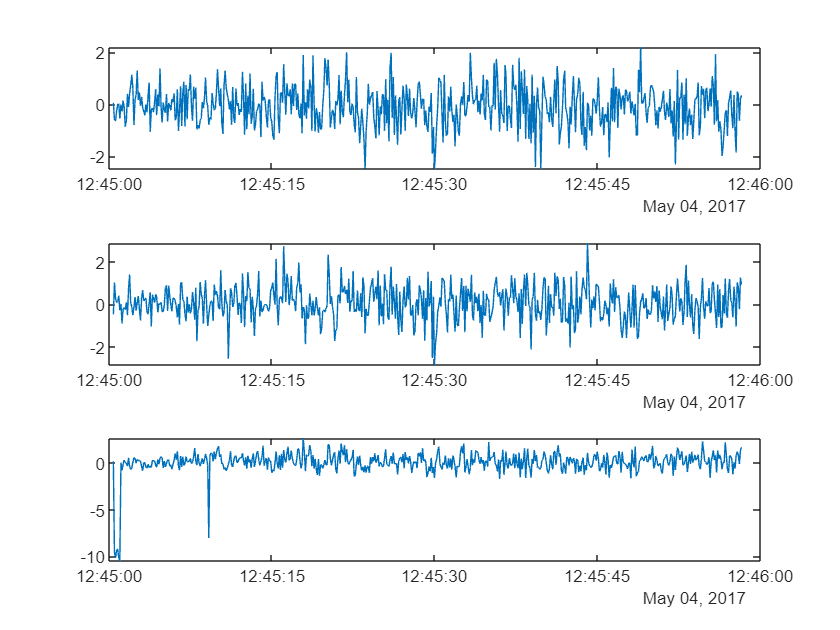

figure()
tiledlayout(3,1);
x = myData.time; 
y1 = myData.accX_body;
y2 = myData.accY_body;
y3 = myData.accZ_body;

% Tile 1
nexttile
plot(x,y1)

% Tile 2
nexttile
plot(x,y2)

% Tile 3
nexttile
plot(x,y3)

## Part 4a: Analyze Flight Data - Logical Indexing

Logical indexing in MATLAB is a powerful approach for finding subsets of data within a large data set that meets certain criteria.

Specify all rows where mode number is 6 (Track Altitude Mode).

%method 1
tic;
idxMode6a = []; 
for i = 1:height(myData)
    if myData.modeNumber(i) == 6
        idxMode6a(end+1) = i;
    end
end
toc

Elapsed time is 0.021332 seconds.


%method 2
tic;
idxMode6b = find(myData.modeNumber == 6);
toc

Elapsed time is 0.006879 seconds.


%method 3
tic;
idxMode6c = myData.modeNumber == 6;
toc

Elapsed time is 0.003355 seconds.


idx6Data = myData(idxMode6c,:)

idx6Data = 6×17 table
            time             modeNumber    accX_body    accY_body    accZ_body        p             q              r         batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1        pos2          pos3       isBallFlag
    _____________________    __________    _________    _________    _________    __________    __________    ___________    ____________    __________    __________    __________    __________    _______ 

## Part 4b: Analyze Flight Data - Timetables

Using the right tool for the right job can really help speed up analysis. Here, we will explore the benefits of using a '[timetable](https://www.mathworks.com/help/matlab/timetables.html)' in MATLAB. 'timetables' have many built-in capabilities that make working with time-series data faster and quicker. Let's explore.

dataTable = myData;
dataStruct = table2struct(myData);
dataTimetable = table2timetable(myData);
whos dataTable dataStruct dataTimetable

  Name                 Size              Bytes  Class        Attributes

  dataStruct         580x1             1126288  struct                 
  dataTable          580x17              85429  table                  
  dataTimetable      580x16              85069  timetable              



**A)  Identify Events**

We can easily find and isolate events based on external criteria using an '[eventtable](https://www.mathworks.com/help/matlab/matlab_prog/find-events-in-timetable-using-event-table.html#FindEventsInTimestampedDataExample-2)'. Let's try an example of finding all troughs in our IMU data in the Z-axis. **(**to go through interval events in hyperlink)**

troughs = find(islocalmin(dataTimetable.accZ_body));
typeLabels = categorical([ones(size(troughs))], 1, "trough");
extremaEvents = extractevents(dataTimetable, troughs,EventLabels=typeLabels)

extremaEvents = 183×1 eventtable
  Event Labels Variable: EventLabels
  Event Lengths Variable: <instantaneous>

            time             EventLabels
    _____________________    ___________

    2017::124:12:45:00.60      trough   
    2017::124:12:45:01.00      trough   
    2017::124:12:45:01.20      trough   
    2017::124:12:45:01.70      trough   
    2017::124:12:45:02.00      trough   
    2017::124:12:45:02.50      trough   
    2017::124:12:45:03.10      trough   
    2017::124:12:45:03.50      trough   
    2017::124:12:45:03.70      trough   
    2017::124:12:45:03.90      trough   
    2017::124:12:45:04.10      trough   
    2017::124:12:45:04.39      trough   
    2017::124:12:45:04.60

**B)  Isolate a minute around timestamp 2017::124:12:45:60.00**

We can easily isolate a certain tolerance of time around a specific event. Lets isolate a minute around the first trough event we notice from earlier.

tol = withtol(datetime('2017::124:12:45:00.60','Format', 'u::DDD:HH:mm:ss.SS'), minutes(1))

tol = 	timetable withtol subscript:

		Select timetable rows matching the following times:

		2017::124:12:45:00.60
		with tolerance of +/- 1 min

	See Select Times in Timetable.


dataTimetable(tol,:)

ans = 580×16 timetable
            time             modeNumber    accX_body     accY_body    accZ_body          p             q              r         batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1       pos2       pos3      isBallFlag
    _____________________    __________    __________    _________    __________    ___________    __________    ___________    ____________    __________    __________    __________    __________    _______

**C)  Join Tables/Timetables together**

We need to gather data corresponding to each of the Operational Phases. The simple approach is model where each **Mode** maps to a single **Phase** (1:1 relationship). 

modeInfo

modeInfo = 10×2 table
    modeNumber      modeName  
    __________    ____________

         1        WaitForComms
         2        Init        
         3        Calibration 
         4        ReadyForTO  
         5        TakeOff     
         6        TrackAlt    
         7        Track3D     
         8        LostBall    
         9        Land        
        10        EmergencyOff


phaseInfo

phaseInfo = 3×2 table
    phaseNumber     phaseName  
    ___________    ____________

         1         GroundRotOff
         2         GroundRotOn 
         3         InFlight    


modeToPhase

modeToPhase = 10×2 table
    phaseNumber     phaseName  
    ___________    ____________

         1         GroundRotOff
         1         GroundRotOff
         1         GroundRotOff
         2         GroundRotOn 
         3         InFlight    
         3         InFlight    
         3         InFlight    
         3         InFlight    
         3         InFlight    
         1         GroundRotOff


Append Phase Number and Phase Name columns to modeInfo table (

modeInfo.phaseNumbers = modeToPhase{:,1};
modeInfo.phaseNames = modeToPhase{:,2};
modeInfo

modeInfo = 10×4 table
    modeNumber      modeName      phaseNumbers     phaseNames 
    __________    ____________    ____________    ____________

         1        WaitForComms         1          GroundRotOff
         2        Init                 1          GroundRotOff
         3        Calibration          1          GroundRotOff
         4        ReadyForTO           2          GroundRotOn 
         5        TakeOff              3          InFlight    
         6        TrackAlt             3          InFlight    
         7        Track3D              3          InFlight    
         8        LostBall             3          InFlight    
         9        Land                 3          InFlight    
        10        EmergencyOff         1          GroundRotOff


% Join tables
joinedData = join(dataTimetable,modeInfo,"Keys","modeNumber")

joinedData = 580×19 timetable
            time             modeNumber    accX_body     accY_body    accZ_body          p             q              r         batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1       pos2       pos3      isBallFlag      modeName      phaseNumbers     phaseNames 
    _____________________    __________    __________    _________    __________    ___________    __________    ___________    ____________    __________    __

dataTimetable = join(dataTimetable,modeInfo,'Keys','modeNumber')

dataTimetable = 580×19 timetable
            time             modeNumber    accX_body     accY_body    accZ_body          p             q              r         batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1       pos2       pos3      isBallFlag      modeName      phaseNumbers     phaseNames 
    _____________________    __________    __________    _________    __________    ___________    __________    ___________    ____________    __________    

## 5: Finish Analysis and Generate Report

**On Ground: Rotor Blades Off**

*Calculate Statistics for Linear Acceleration*

%Generate table of data when Flight  Phase equals "GroundRotOff"
RawGroundRotOff = dataTimetable(dataTimetable.phaseNames == "GroundRotOff",:);
statsRawGroundRotOff = table();

%Average
statsRawGroundRotOff.Average  =  mean( [  ...
                                                RawGroundRotOff.accX_body...
                                                RawGroundRotOff.accY_body...
                                                RawGroundRotOff.accZ_body...
                                                RawGroundRotOff.p...
                                                RawGroundRotOff.q...
                                                RawGroundRotOff.r ] )' ;
%Standard Deviation                                       
statsRawGroundRotOff.Sigma    =  std( [  ...
                                                RawGroundRotOff.accX_body...
                                                RawGroundRotOff.accY_body...
                                                RawGroundRotOff.accZ_body...
                                                RawGroundRotOff.p...
                                                RawGroundRotOff.q...
                                                RawGroundRotOff.r  ] )' ;
%Maximum                                            
statsRawGroundRotOff.Maximum   =  max( [  ...
                                                RawGroundRotOff.accX_body...
                                                RawGroundRotOff.accY_body...
                                                RawGroundRotOff.accZ_body...
                                                RawGroundRotOff.p...
                                                RawGroundRotOff.q...
                                                RawGroundRotOff.r  ] )' ; 
                                            
%Minimum                                                
statsRawGroundRotOff.Minimum   =  min( [  ...  
                                                RawGroundRotOff.accX_body...
                                                RawGroundRotOff.accY_body...
                                                RawGroundRotOff.accZ_body...
                                                RawGroundRotOff.p...
                                                RawGroundRotOff.q...
                                                RawGroundRotOff.r  ] )' ;                                           
                                       
%RowNames of the Table
statsRawGroundRotOff.Properties.RowNames = {'accX_body' 'accY_body' 'accZ_body' 'p' 'q' 'r'};        

**On Ground: Rotor Blades On**

*Calculate Statistics for Linear Acceleration*

RawGroundRotOn   = dataTimetable(dataTimetable.phaseNames == "GroundRotOn",:);
statsRawGroundRotOn = table();

%Average
statsRawGroundRotOn.Average  =  mean( [  RawGroundRotOn.accX_body ...
                                            RawGroundRotOn.accY_body ...
                                            RawGroundRotOn.accZ_body...
                                            RawGroundRotOn.p...
                                            RawGroundRotOn.q...
                                            RawGroundRotOn.r  ] )' ;
                                                
%Standard Deviation                                       
statsRawGroundRotOn.Sigma    =  std( [   RawGroundRotOn.accX_body...
                                            RawGroundRotOn.accY_body...
                                            RawGroundRotOn.accZ_body...
                                            RawGroundRotOn.p...
                                            RawGroundRotOn.q...
                                            RawGroundRotOn.r   ] )' ;
                                                
%Maximum                                            
statsRawGroundRotOn.Maximum   =  max( [  RawGroundRotOn.accX_body...
                                            RawGroundRotOn.accY_body...
                                            RawGroundRotOn.accZ_body...
                                            RawGroundRotOn.p...
                                            RawGroundRotOn.q...
                                            RawGroundRotOn.r   ] )' ; 
                                                
                                            
%Minimum                                                
statsRawGroundRotOn.Minimum   =  min( [  RawGroundRotOn.accX_body...
                                            RawGroundRotOn.accY_body...
                                            RawGroundRotOn.accZ_body...
                                            RawGroundRotOn.p...
                                            RawGroundRotOn.q...
                                            RawGroundRotOn.r   ] )' ;                                             
                                       
%RowNames of the Table
statsRawGroundRotOn.Properties.RowNames = {'accX_body' 'accY_body' 'accZ_body' 'p' 'q' 'r'};        

**In Flight**

*IMU Acceleration Statistics during Flight Phase #3 - In Flight (Rotors ON)*

RawInFlight = dataTimetable(dataTimetable.phaseNames == "InFlight",:);
statsRawInFlight = table();

statsRawInFlight.Average =   mean ( [ RawInFlight.accX_body...
                                         RawInFlight.accY_body...
                                         RawInFlight.accZ_body...
                                         RawInFlight.p...
                                         RawInFlight.q...
                                         RawInFlight.r   ] )' ;

                                       
statsRawInFlight.Sigma  =  std ( [    RawInFlight.accX_body...
                                         RawInFlight.accY_body...
                                         RawInFlight.accZ_body...
                                         RawInFlight.p...
                                         RawInFlight.q...
                                         RawInFlight.r ] )' ;
                                           
%Maximum                                            
statsRawInFlight.Maximum  =  max ( [  RawInFlight.accX_body...
                                         RawInFlight.accY_body...
                                         RawInFlight.accZ_body...
                                         RawInFlight.p...
                                         RawInFlight.q...
                                         RawInFlight.r ] )' ;  
                                                
                                            
%Minimum                                                
statsRawInFlight.Minimum  =  min ( [  RawInFlight.accX_body...
                                         RawInFlight.accY_body...
                                         RawInFlight.accZ_body...
                                         RawInFlight.p...
                                         RawInFlight.q...
                                         RawInFlight.r ] )' ;   
                                                                                                                                
%RowNames of the Table
statsRawInFlight.Properties.RowNames = {'accX_body' 'accY_body' 'accZ_body' 'p' 'q' 'r'};        

### Statistics for IMU Acceleration for Each Phase of Flight

**Phase 1: On Ground with Rotors OFF**

statsRawGroundRotOff

statsRawGroundRotOff = 6×4 table
                   Average        Sigma       Maximum      Minimum  
                 ___________    _________    _________    __________

    accX_body       0.032553      0.55327       1.3826       -1.0574
    accY_body         0.0378      0.49734       1.3939       -1.0491
    accZ_body       -0.73705       2.7047       1.5786       -10.505
    p            -0.00021922    0.0014737    0.0024617    -0.0042611
    q             0.00026512    0.0011632    0.0026282    -0.0027142
    r             0.00018186    0.0013238    0.0038337    -0.0026653


Does this make sense? Why is the sigma for the acceleration in the Z-axis so large? Let's plot the data real quick to see what's going on...

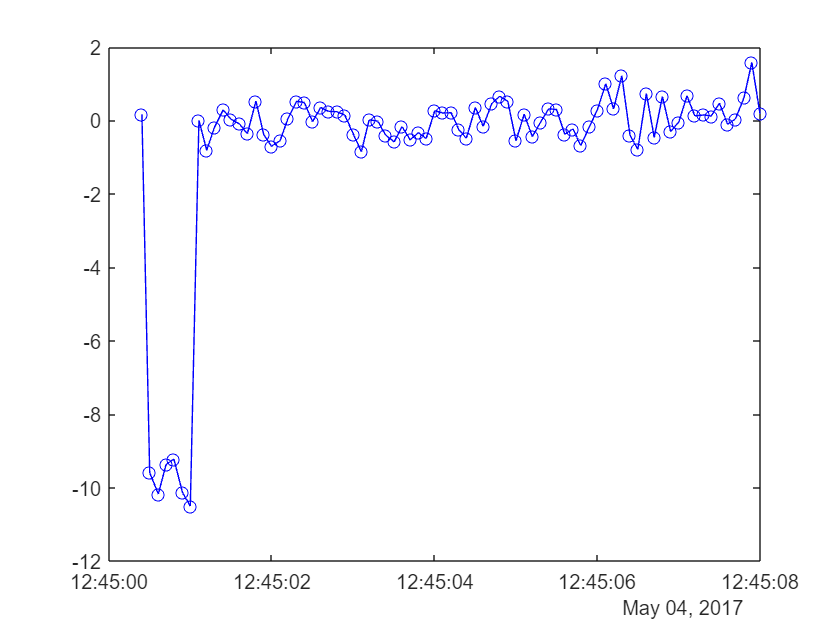

figure
plot(RawGroundRotOff.time, RawGroundRotOff.accZ_body, 'o-b');

Before the onboard calibration is complete, we see gravity in the raw Z-axis of the IMU accelerometer data. Once the calibration routine begins, we can see this bias being subtracted out. This is distorting our statistics and we have a few options to deal with the distortion:

- Treat the uncalibrated data points as outliers

- Ignore all data until calibration is complete

- Subtract out the known gravity bias where it is polluting the data

For now, let's use option 1. We can do this in a live task.

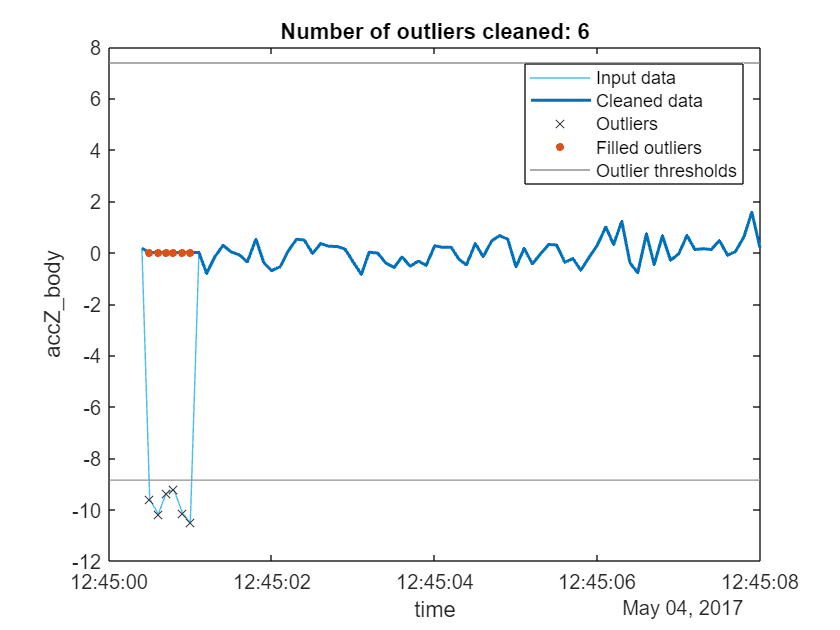

% Fill outliers
[newTable,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(RawGroundRotOff,"next","mean","DataVariables","accZ_body");

% Display results
figure
plot(RawGroundRotOff.time,RawGroundRotOff.accZ_body,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(RawGroundRotOff.time,newTable.accZ_body,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(RawGroundRotOff.time(outlierIndices(:,4)),RawGroundRotOff.accZ_body(outlierIndices(:,4)),...
    "x","Color",[64 64 64]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(RawGroundRotOff.time(outlierIndices(:,4)),newTable.accZ_body(outlierIndices(:,4)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim],...
    [thresholdLow.accZ_body*[1 1] NaN thresholdHigh.accZ_body*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,4)))
legend
ylabel("accZ_body","Interpreter","none")
xlabel("time")

clear thresholdLow thresholdHigh

## Part 6: App Designer

Let's explore briefly on how we can build a front-end for this analysis we just created. We can start by opening up [App Designer](https://www.mathworks.com/products/matlab/app-designer.html) by calling it programmatically or by pressing the **Design App** icon in the apps toolstrip.